# Franka Emika Panda Workspace using FK_SpaceForm 3D

clc; clear; close;

#### Start parallel computing pool

pool = parpool();

Starting parallel pool (parpool) using the 'Processes' profile ...
Connected to the parallel pool (number of workers: 4).


#### Define the transformation matrices for the Franka Emika Panda Robot

panda_model()
vpa(M, 4)

$$ans = \left(\begin{array}{cccc} 1.0 & 0 & 0 & 0.088\\ 0 & -1.0 & 0 & 0\\ 0 & 0 & -1.0 & 0.926\\ 0 & 0 & 0 & 1.0 \end{array}\right)$$

vpa(S, 4)

$$ans = \left(\begin{array}{ccccccc} 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 1.0 & 0 & -1.0 & 0 & -1.0 & 0\\ 1.0 & 0 & 1.0 & 0 & 1.0 & 0 & -1.0\\ 0 & -0.333 & 0 & 0.649 & 0 & 1.033 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0.088\\ 0 & 0 & 0 & -0.0825 & 0 & 0 & 0 \end{array}\right)$$

#### Defining joint limits for all joints

qlim = panda.qlim

qlim =    -2.8973    2.8973
   -1.7628    1.7628
   -2.8973    2.8973
   -3.0718   -0.0698
   -2.8973    2.8973
   -0.0175    3.7525
   -2.8973    2.8973


vpa(qlim, 5)

$$ans = \left(\begin{array}{cc} -2.8973 & 2.8973\\ -1.7628 & 1.7628\\ -2.8973 & 2.8973\\ -3.0718 & -0.0698\\ -2.8973 & 2.8973\\ -0.0175 & 3.7525\\ -2.8973 & 2.8973 \end{array}\right)$$

#### Generate a set of discrete joint angles within the joint limits


for i=1:size(qlim, 1)
    Qlim(i, :) = linspace(qlim(i, 1), qlim(i, 2), 5);
end
Qlim

Qlim =    -2.8973   -1.4486         0    1.4486    2.8973
   -1.7628   -0.8814         0    0.8814    1.7628
   -2.8973   -1.4486         0    1.4486    2.8973
   -3.0718   -2.3213   -1.5708   -0.8203   -0.0698
   -2.8973   -1.4486         0    1.4486    2.8973
   -0.0175    0.9250    1.8675    2.8100    3.7525
   -2.8973   -1.4486         0    1.4486    2.8973


#### Generate all possible combinations of joint angles for the robot

Q = unique(combvec(Qlim(1, :), Qlim(2, :), Qlim(3, :), Qlim(4, :), Qlim(5, :), Qlim(6, :), Qlim(7, :))', 'rows');


Q

Q =    -2.8973   -1.7628   -2.8973   -3.0718   -2.8973   -0.0175   -2.8973
   -2.8973   -1.7628   -2.8973   -3.0718   -2.8973   -0.0175   -1.4486
   -2.8973   -1.7628   -2.8973   -3.0718   -2.8973   -0.0175         0
   -2.8973   -1.7628   -2.8973   -3.0718   -2.8973   -0.0175    1.4486
   -2.8973   -1.7628   -2.8973   -3.0718   -2.8973   -0.0175    2.8973
   -2.8973   -1.7628   -2.8973   -3.0718   -2.8973    0.9250   -2.8973
   -2.8973   -1.7628   -2.8973   -3.0718   -2.8973    0.9250   -1.4486
   -2.8973   -1.7628   -2.8973   -3.0718   -2.8973    0.9250         0
   -2.8973   -1.7628   -2.8973   -3.0718   -2.8973    0.9250    1.4486
   -2.8973   -1.7628   -2.8973   -3.0718   -2.8973    0.9250    2.8973


#### Remove duplicate joint angles

uniqueQ = unique(Q, 'rows');
numDuplicates = size(Q,1) - size(uniqueQ,1)

numDuplicates = 0

####  Compute the forward kinematics for each unique set of joint angles

parfor i = 1:size(uniqueQ,1)
    T =  fkine(panda, uniqueQ(i, :));
    X(i) = T.t(1);
    Y(i) = T.t(2);
    Z(i) = T.t(3);
end


#### Delete the parallel computing pool

delete(pool);

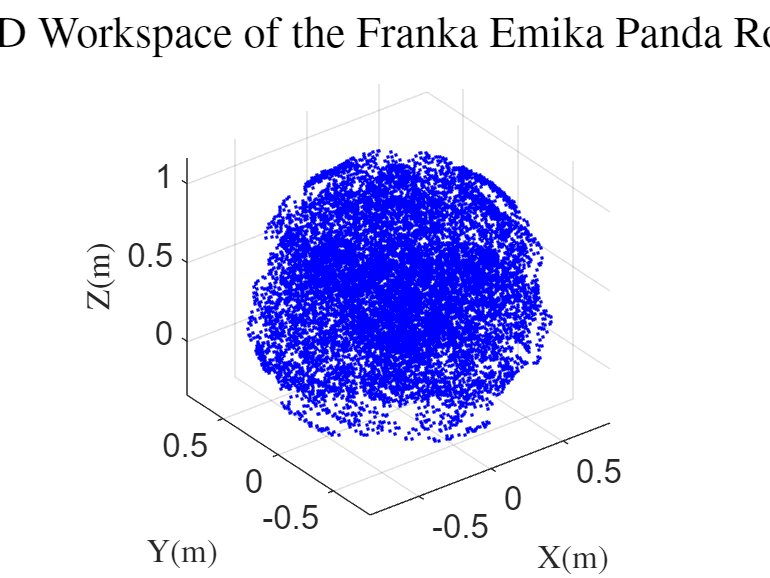



scatter3(X, Y, Z, 'b.');

ax = gca;
ax.FontSize = 18;
xlabel('X(m)', 'FontSize', 18, 'Interpreter','latex');
ylabel('Y(m)', 'FontSize', 18, 'Interpreter','latex');
zlabel('Z(m)', 'FontSize', 18, 'Interpreter','latex');
title('3-D Workspace of the Franka Emika Panda Robot', 'FontSize', 24, 'Interpreter','latex');
axis equal;